## Random networks

You have to perform a simulation. You need a high number of random networks of a given dimensions. You want to compute the distribution of the degree of a specific node given the ensemble of simulated networks. We have n nodes and we compute degree distribution for a given node within this network.

Assumption: directed network

function interaction_table = gen_rand_net(N_nodes, N_edges)

adj_matrix = zeros(N_nodes)
rand_indexes = randperm(N_nodes*N_nodes, N_edges )

adj_matrix(rand_indexes)=1;

[source, target] = find(adj_matrix == 1);
interaction_table = [source target]
end


n_networks = 100;
n_nodes = 10;
n_edges = 15;

deg_matrix = zeros(n_nodes, n_networks)

for i=1:n_networks
    int_table = gen_rand_net(n_nodes, n_edges);
    G = digraph(int_table(:,1),int_table(:,2));
    deg_matrix(:,i) = degree(G)
        


## Reachable nodes in 3 steps

Given the node A count all the nodes that are reached by A with at most 3 steps

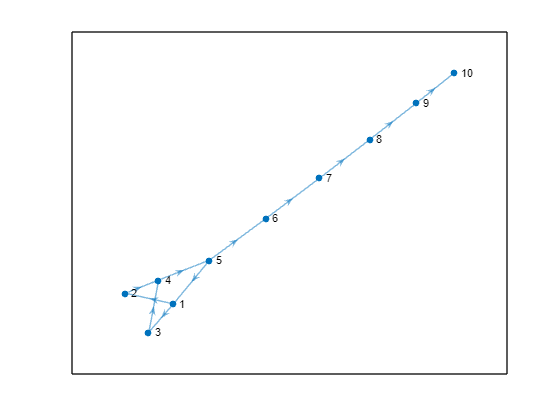

A = 1;

% The matrix is build just to text the example

% Number of nodes in the graph
numNodes = 10;

% Initialize an empty adjacency matrix
adjMatrix = zeros(numNodes, numNodes);

% Edges in the directed graph
edges = [1, 2; 1, 3; 2, 4; 3, 4; 4, 5; 5, 1; 5, 6; 6, 7; 7, 8; 8, 9; 9, 10];

G = digraph(edges(:,1),edges(:,2));
plot(G)

[tree, dist] = shortestpathtree(G,A)

tree =   digraph with properties:

    Edges: [9×1 table]
    Nodes: [10×0 table]


dist =      0     1     1     2     3     4     5     6     7     8


sum(dist <= 3 & dist > 0)

ans = 4

## Find hubs

Starting from an adjacency matrix, identify the isolated hubs of the network, considering a hub a gene with at least degree=10. We consider isolated hubs as hubs that are not connected between them.

Here the code to build the adjacency matrix of a random network containing some hubs and some isolated hubs. This is just to run the code with meaningful data.

% Parameters
numNodes = 100; % Number of nodes in the network
minDegree = 10; % Minimum degree required for specified nodes

probability = 0.01; % Probability of connection between nodes

% Generate an initial random graph
G = graph;

% Add connections based on the specified probability
for i = 1:numNodes
    for j = i+1:numNodes
        if rand < probability
            G = addedge(G, i, j);
        end
    end
end

% Ensure that specified nodes have a degree greater than or equal to 10
nodesToIncrease = [10, 20, 30, 40, 50, 60, 70, 80, 90];
for i = 1:length(nodesToIncrease)
    currentNode = nodesToIncrease(i);
    currentDegree = degree(G, currentNode);
    
    if currentDegree < minDegree
        % Add connections until the node's degree reaches the desired value
        addedConnections = 0;
        while degree(G, currentNode) < minDegree
            randomNode = randi(numNodes);
            if randomNode ~= currentNode && ~ismember(table([currentNode,randomNode], 'VariableNames', {'EndNodes'}), G.Edges)
                G = addedge(G, currentNode, randomNode);
                addedConnections = addedConnections + 1;
            end
        end
        fprintf('Added %d connections to node %d\n', addedConnections, currentNode);
    end
end

Added 9 connections to node 10
Added 9 connections to node 20
Added 7 connections to node 30
Added 10 connections to node 40
Added 9 connections to node 50
Added 9 connections to node 60
Added 9 connections to node 70
Added 9 connections to node 80
Added 7 connections to node 90


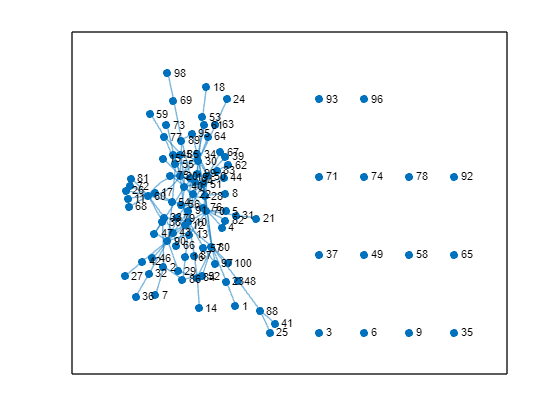

plot(G, 'Layout', 'force', 'MarkerSize', 5)

hubs = find(degree(G) >= 10)

hubs =     10
    20
    30
    40
    50
    60
    70
    80
    90


tree =   digraph with properties:

    Edges: [85×1 table]
    Nodes: [100×0 table]


dist =      4     3   Inf     2     2   Inf     4     4   Inf     0     3     3     2     3     4     1     3     4     1     3     3     1     3     4     5     3     4     3     3     2     2     3     1     3   Inf     4   Inf     3     3     2     5     3     1     3     3     3     2     3   Inf     2


tree =   digraph with properties:

    Edges: [85×1 table]
    Nodes: [100×0 table]


dist =      4     3   Inf     3     3   Inf     4     3   Inf     3     2     1     3     4     1     4     3     3     2     0     4     2     3     3     5     2     4     2     3     1     3     3     2     1   Inf     4   Inf     2     3     2     5     3     3     2     1     3     3     3   Inf     2


tree =   digraph with properties:

    Edges: [85×1 table]
    Nodes: [100×0 table]


dist =      4     4   Inf     2     2   Inf     5     2   Inf     2     3     2     2     4     2     3     3     2     2     1     3     1     3     2     5     3     5     1     4     0     2     4     3     1   Inf     5   Inf     3     2     2     5     4     3     3     2     4     4     3   Inf     1


tree =   digraph with properties:

    Edges: [85×1 table]
    Nodes: [100×0 table]


dist =      4     2   Inf     3     3   Inf     3     2   Inf     2     3     3     3     4     3     3     4     4     2     2     4     3     3     4     5     3     5     1     4     2     3     4     3     2   Inf     5   Inf     1     3     0     5     4     3     2     1     4     2     3   Inf     2


tree =   digraph with properties:

    Edges: [85×1 table]
    Nodes: [100×0 table]


dist =      4     4   Inf     3     3   Inf     5     3   Inf     2     4     3     3     4     3     3     4     3     1     2     4     1     3     3     5     4     4     2     3     1     3     3     3     1   Inf     4   Inf     3     1     2     5     3     3     3     3     3     3     3   Inf     0


tree =   digraph with properties:

    Edges: [85×1 table]
    Nodes: [100×0 table]


dist =      5     2   Inf     3     3   Inf     3     4   Inf     2     1     2     3     5     2     3     2     4     3     1     4     3     4     4     6     1     4     3     3     2     3     3     1     2   Inf     4   Inf     1     4     2     6     3     2     3     2     3     2     4   Inf     3


tree =   digraph with properties:

    Edges: [85×1 table]
    Nodes: [100×0 table]


dist =      3     4   Inf     1     1   Inf     5     3   Inf     1     3     2     1     3     3     2     2     3     2     2     2     2     2     3     4     3     4     2     3     1     1     3     2     2   Inf     4   Inf     3     3     2     4     3     2     2     3     3     3     2   Inf     2


tree =   digraph with properties:

    Edges: [85×1 table]
    Nodes: [100×0 table]


dist =      2     3   Inf     2     2   Inf     4     2   Inf     2     4     1     2     2     3     3     3     4     3     2     3     3     1     4     3     4     4     1     2     2     2     3     3     3   Inf     4   Inf     3     3     2     3     3     3     3     3     3     3     1   Inf     2


tree =   digraph with properties:

    Edges: [85×1 table]
    Nodes: [100×0 table]


dist =      4     3   Inf     3     3   Inf     4     4   Inf     2     3     1     1     3     3     3     2     5     3     2     4     2     3     5     5     3     2     3     1     3     3     1     2     3   Inf     2   Inf     2     3     3     5     1     3     4     3     1     1     3   Inf     2


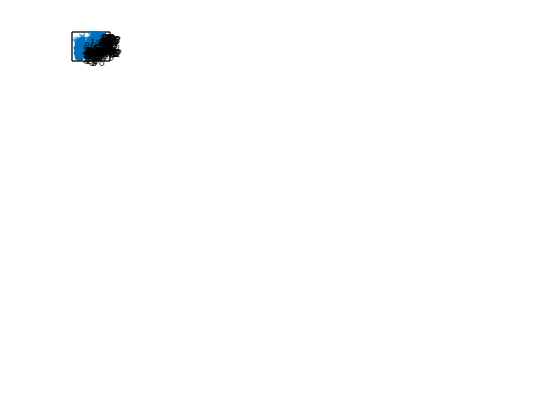

% subplot(length(hubs),length(hubs),1)
for i = 1:length(hubs)
   [tree, dist] = shortestpathtree(G,hubs(i))
   
   plot(tree)
end

REPRESSILATOR

t_end= 6*60

m10 = 0             m20 = 0                 m30 = 0

p10 = 200           p20 = 0                 p30 = 0

function dydt = repressilator_exam(t,y)                            % y(n) has as many n indexes as the number of initial conditions given to ode45 (1 condition = 1 curve)
global Km Kd gamma_1 gamma_2 gamma_3 n_1 n_2 n_3 Kd_1 Kd_2 Kd_3 gamma0 Kp T

dydt(1,:) = gamma0 - Km*y(1) + (gamma_1/(1+(y(4)/Kd_3)^n_3))       % dynamic equations 
dydt(2,:) =
dydt(3,:) = 

dydt(4,:) = -Kp*y(4) + T*y(1)
dydt(5,:) = -Kp*y(5) + T*y(2)
dydt(6,:) = -Kp*y(6) + T*y(3)
end

sol = ode45(@repressilator,[0 t_end],[m10 p10])
plot(sol.x, sol.y(1,:))

## Nullclines and vector field

X = linspace(0,Xmax,numpoints)              % I have no idea how this interval I want to see is chosen

X_null = ... % nullcline equation 1    uses X in its definition
Y_null = ... % nullcline equation 2

Ymesh = linspace(min([X_null Y_null]),max([X_null Y_null]),numpoints);
[Xquiv, Yquiv] = meshgrid(X,Ymesh)

dx = ... & dynamics equation 1         uses Xquiv and Yquiv in its definition
dy = ... % dynamics equation 2

quiver(Xquiv, Yquiv, dx, dy)

## From Edge table to adj matrix

numNodes = 10;                                  % Number of nodes in the graph
adjMatrix = zeros(numNodes, numNodes);          % Initialize an empty adjacency matrix
edges = [1, 2; 1, 3; 2, 4; 3, 4; 4, 5; ...
    5, 1; 5, 6; 6, 7; 7, 8; 8, 9; 9, 10];       % Edges in the directed graph


for i = 1:size(edges, 1)                        % for each row in the edge table
    fromNode = edges(i, 1);                         % take the 1st node of the edge
    toNode = edges(i, 2);                           % take the 2nd node of the edge
    
    adjMatrix(fromNode, toNode) = 1;                % update corresponding cell in the adj matrix       (directed network in this case since only one)
end

## From Adj matrix to edge table

[source, target] = find(adjMatrix == 1);
edge_table = [source target]

## Number of nodes that are rechable from node 1 in at most n steps

A = 1
n_max_steps = 3;
n_reachables = 0;
for i=1:n_max_steps
    mat = adjMatrix^i                                       % the value in the cell indicates how many differenth paths of that length connect the two nodes
    n_reachables = n_reachables + length(find(mat(A,:)>=1));     % take the first row for each power and count the number of cells having a value, then recursively add for all the powers tested
end

## **Hubs identification**

adj_mat = full(adjacency(G));
n_nodes = size(adj_mat,1);
hubs = [];
for i=1:n_nodes
    if sum(adj_mat(i,:)) >= 10                   % very similar to n_reachables before, but in this case I can simply sum cause I have only 0s and 1s
        hubs = [hubs,i];
    end
end
hubs

## Bipartite graph;    from adj mat to 1n-proj

M = zeros(n + m, n + m);
M(1:n, n + 1:end) = randi([0 1], n, m);  
M = M + M'; 

P = M'*M;             
for i=1:n+m           
    P(i,i)=0;
end

## Bipartite graph;    from contingency table to 1n-proj

## From adj list to adj matrix

adj_list = {
    {[1 2], [1 4]};
    {[2 3], [2 4]};
    {[3 1]};
    {}
    }

n_nodes = length(adj_list);
adj_mat = zeros(n_nodes);
for i=1:n_nodes
    n_neighbors = length(adj_list{i});
    for j=1:n_neighbors
        adj_mat(i,adj_list{i}{j}(2)) = 1;
    end
end
display(adj_mat);

## Random network adjacency matrix 

adjacency_matrix = zeros(N_nodes);                             
edges_idxs = randperm(N_nodes*N_nodes, A_arrows);         
adjacency_matrix(edges_idxs)=1; 